# Aula 09 - Diagramas de Bode e Carta de Nichols

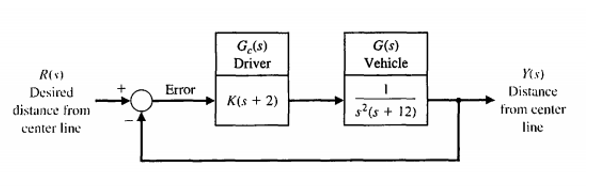

a) Plotar o diagrama de bode de malha aberta para $K=1$

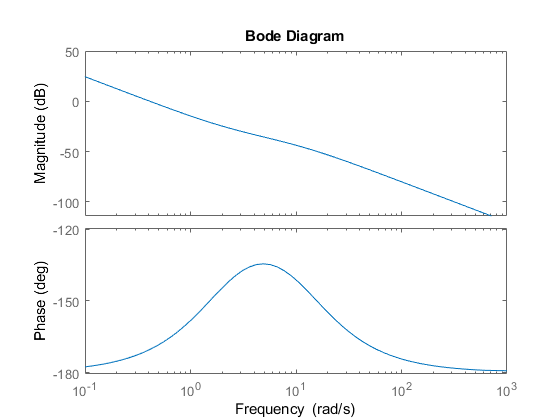

clear
s=tf([1,0],1);
Gc=s+2;
G=1/(s^2*(s+12));
bode(Gc*G)

b) Plotar o diagrama de bode de malha fechada para $K=1$

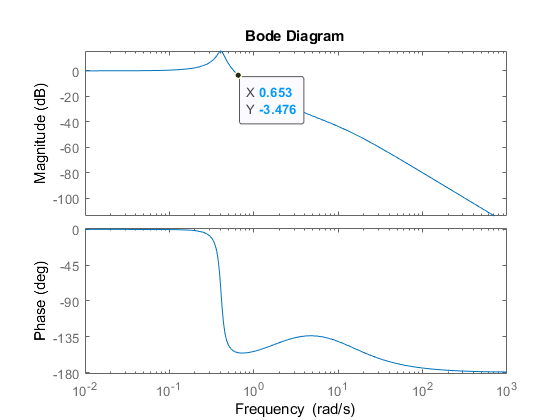

sys=feedback(Gc*G,1);
bode(sys)

c) Refazer os itens a) e b) para $K=50$

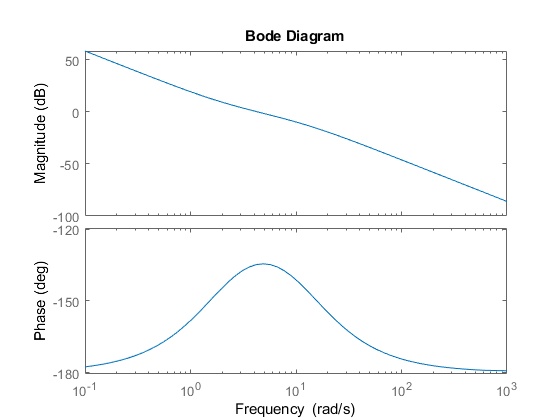

K=50;
sys_ma=K*Gc*G;
bode(sys_ma)

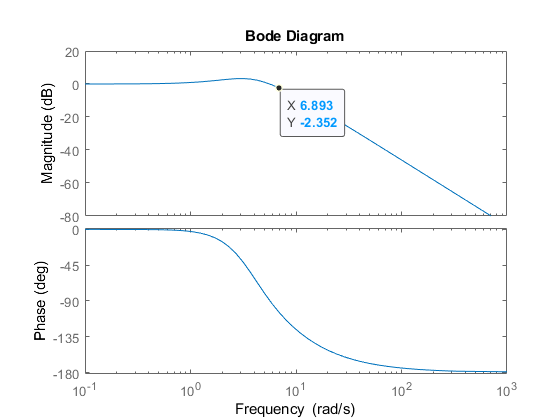

sys_mf=feedback(sys_ma,1);
bode(sys_mf)

d) Determinar o valor de $K$ para o qual o $M= \frac{X+Yj}{1+X+Yj} \leq2$ e a largura de banda é a maior possível

A largura de banda é a diferença entre a frequência na qual o módulo do diagrama de bode é -3dB e a frequência na qual ele é 0dB. 

% para K=1
sys_ma=G*Gc;
sys_mf=feedback(sys_ma,1);
[mag,phase,wout] = bode(sys_mf);
wc=interp1(20*log10(mag(:)),wout,-3) % lembrar que a variável Mag guarda o módulo sem ser em dB

wc = 0.6428

% para K=50
sys_ma=K*G*Gc;
sys_mf=feedback(sys_ma,1);
[mag,phase,wout] = bode(sys_mf);
wc=interp1(20*log10(mag(:)),wout,-3) % lembrar que a variável Mag guarda o módulo sem ser em dB

wc = 26.7417

Podemos ver que a largura de banda aumenta com K.

Além disso, queremos $M\leq2=6dB$. Esse $M$ é obtido pelo diagrama de Nichols. Vamos então plotar esse diagrama para diferentes valores de $K$

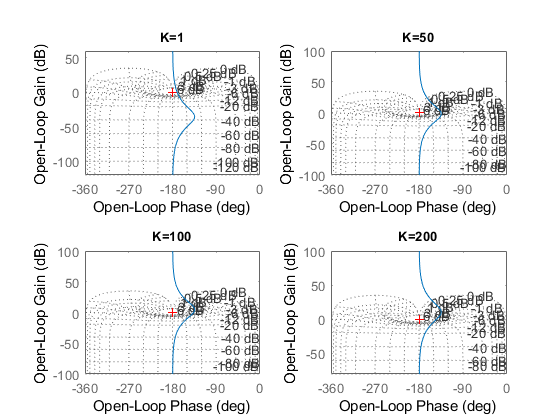

subplot(2,2,1);
sys_ma=G*Gc;
nichols(sys_ma)
grid on
title('K=1')
subplot(2,2,2);
K=50;
sys_ma=K*G*Gc;
nichols(sys_ma)
grid on
title('K=50')
subplot(2,2,3);
K=100;
sys_ma=K*G*Gc;
nichols(sys_ma)
title('K=100')
grid on
subplot(2,2,4);
K=200;
sys_ma=K*G*Gc;
nichols(sys_ma)
grid on
title('K=200')

Podemos ver que a curva em azul da função de malha aberta é deslocada para cima confome aumentamos $K$. Se queremos $M\leq2$, devemos fazer com que a curva tangencie o círculo de 6dB sem penetrar o mesmo. Além disso, se queremos maximizar a largura de banda, devemos fazer com que o comprimento na curva azul entre os pontos que cruzam os circulos de 0dB e -3dB seja o maior possível. Pelo gráfico, podemos ver que a situação que satisfaz os 2 requisitos ocorre quando o lado inferior da curva azul toca o círculo de 6dB.

Podemos fazer isso por tentativa e erro ou plotando M e a largura de banda em função de K.

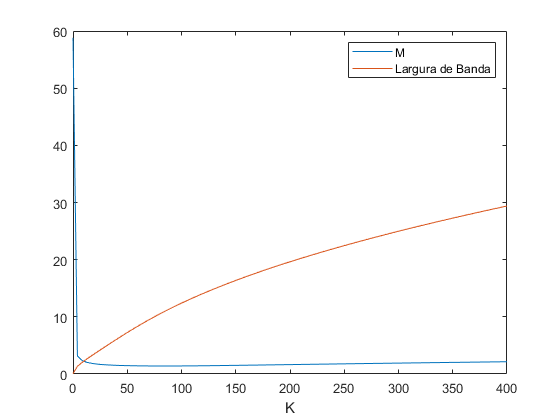

k=linspace(0.01,400,100);
M=zeros(1,length(k));
BW=zeros(1,length(k));
for i=1:length(k)
    sys=feedback(k(i)*G*Gc,1);
    M(i)=getPeakGain(sys); % pega o maior valor de M
    BW(i)=bandwidth(sys); % pega a largura de banda
end
figure()
plot(k,M)
hold on
plot(k,BW)
hold off
xlabel('K')
legend('M','Largura de Banda')

K=interp1(M,k,2)

K = 337.8019


$$K=337,8$$


testando:

sys=feedback(K*G*Gc,1);
getPeakGain(sys)

ans = 2.0000

bandwidth(sys)

ans = 26.7247

e) Determinar o erro em regime para uma entrada rampa


$$K_v=\lim_{s\rightarrow0}sG_{MA}(s)=\lim_{s\rightarrow0}sK\frac{(s+2)}{s^2(s+12)}\rightarrow\infty$$



$$e_{ss}=\frac{1}{K_v}=0$$


O erro em regime para entrada degrau será nulo independente do valor de $K$, pois o sistema é tipo 2. Porém podemos verificar isso por simulação também.

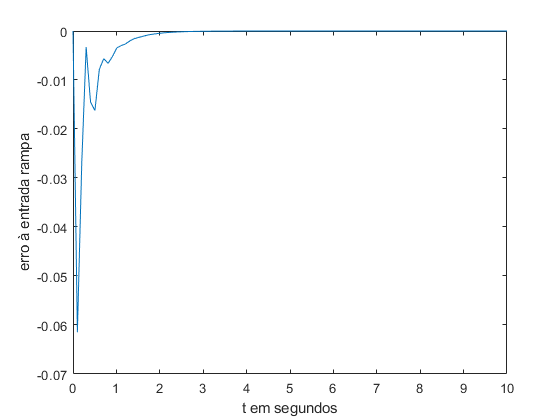

t=linspace(0,10,100);
y=step(sys_mf/s,t); % resposta à rampa
r=step(1/s,t); % entrada rampa
e=y-r;
plot(t,e)
xlabel('t em segundos')
ylabel('erro à entrada rampa')

Há um pouco de erro no início, talvez pela inércia do sistema, mas em menos de 3 segundos o sistema estabiliza e o erro é zerado.